# HW3

# Name - Vinay Patil

# NetId - vpatil3

## **1)**

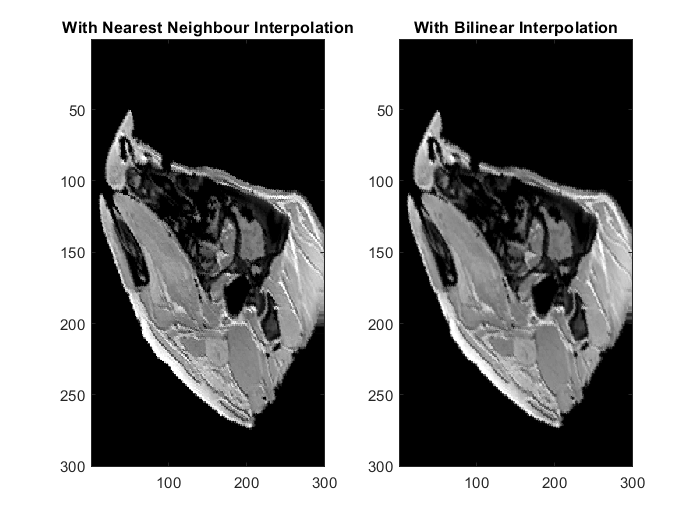

img=imread('PorkyPig.jpg');
angle = -20;

%Matrices to store rotated images
rotimgN=zeros(size(img));
rotimgB=zeros(size(img));

%Helper matrix for bilinear interpolation
rhoMat=zeros(2,2);

%Rotation matrix
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat_inv=inv(rotmat);

%Using shift to preserving the whole orange piece after rotation
shift = zeros(2,1);
shift(1,1) = floor(size(img,1)/2);
shift(2,1) = floor(size(img,2)/2);
rhoN = 0;
rhoB = 0;

rowSize = size(img,1);
colSize = size(img,2);

for i=1:rowSize
    for j=1:colSize
        newpix(1,1)=i;
        newpix(2,1)=j;
        
        %Roated pixel before interpolation
        val = rotmat_inv*(newpix-shift)+shift;
        
        %Nearest Neighbour Interpolation
       	oldpix=round(val);
        if (oldpix(1,1) > 0) && (oldpix(1,1) < size(img,1)) && (oldpix(2,1) > 0) && (oldpix(2,1) < size(img,2))
            %Calculating rho value
            rhoN=img(oldpix(1,1),oldpix(2,1));
        end
        
        %Holds the rotated image (Using NN Interpolation)
       	rotimgN(i,j)=rhoN;
        
        %----------------------------------------------------------------------------------------------------------------
        
        %Bilinear Interpolation
        pivot00i=floor(val(1,1));
        pivot00j=floor(val(2,1));
        
        if (pivot00i >= 1 && pivot00i < rowSize && pivot00j >= 1 && pivot00j < colSize)
            
            rho00=img(pivot00i,pivot00j);
            rho01=img(pivot00i,(pivot00j+1));
            rho10=img((pivot00i+1),pivot00j);
            rho11=img((pivot00i+1),(pivot00j+1));
            
            %Creating left vector
            leftVect=[1-j/colSize,j/colSize];
            
            %Creating rho matrix
            rhoMat(1,1)=rho00;
            rhoMat(1,2)=rho10;
            rhoMat(2,1)=rho01;
            rhoMat(2,2)=rho11;
            
            %Creating right vector
            rightVect=transpose([1-i/rowSize,i/rowSize]);
            
            %Calculating rho value
            rhoB = leftVect*rhoMat*rightVect;
        end
        
        %Holds the rotated image (Using BL Interpolation)
        rotimgB(i,j)= rhoB;
    end
end

colormap('gray');
subplot(1,2,1);
imagesc(rotimgN);
title("With Nearest Neighbour Interpolation");
subplot(1,2,2);
imagesc(rotimgB);
title("With Bilinear Interpolation");

## **2)**

CT = imread("CT.jpg");

%Computing intensity counts. Creating vector of zeros
countsCT = zeros(1,max(CT(:))+1);

for i=1:size(CT,1)
    for j=1:size(CT,2)
        rho1=CT(i,j)+1;
        %Incrementing bin count
        countsCT(rho1)=countsCT(rho1)+1;
    end
end

%Computing intensity probability
probabilitiesCT = countsCT/(size(CT,1)*size(CT,2));

%Excluding zeros
probabilitiesCT = probabilitiesCT(probabilitiesCT>0);

%Computing Entropy
Entropy_For_CT = sum(probabilitiesCT.*log(1./probabilitiesCT));
disp("Entropy for CT is "+num2str(Entropy_For_CT));

Entropy for CT is 2.8



T1 = imread("T1.jpg");
%Computing intensity counts. Creating vector of zeros
countsT1 = zeros(1,max(T1(:))+1);

for i=1:size(T1,1)
    for j=1:size(T1,2)
        rho1=T1(i,j)+1;
        countsT1(rho1)=countsT1(rho1)+1;
    end
end

%Computing intensity probability
probabilitiesT1 = countsT1/(size(T1,1)*size(T1,2));

%Excluding zeros
probabilitiesT1 = probabilitiesT1(probabilitiesT1>0);

%Computing Entropy
Entropy_For_T1 = sum(probabilitiesT1.*log(1./probabilitiesT1));
disp("Entropy for T1 is "+num2str(Entropy_For_T1));

Entropy for T1 is 2.0022


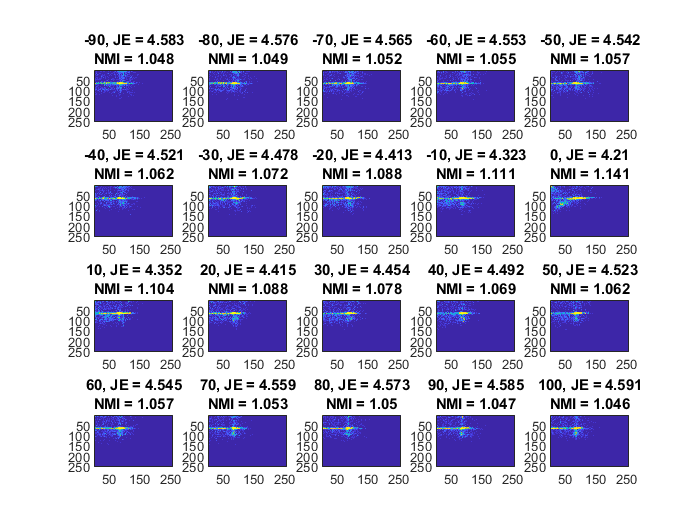

figure
for a=-9:10
    rotimg=zeros(388,388);
    angle=a*10;
    rotmat=zeros(2,2);
    rotmat(1,1)=cos(angle*pi/180);
    rotmat(1,2)=-sin(angle*pi/180);
    rotmat(2,1)=sin(angle*pi/180);
    rotmat(2,2)=cos(angle*pi/180);
    invrotmat=transpose(rotmat);
    oldpix=zeros(2,1);
    newpix=zeros(2,1);
    shift=transpose([194,194]);
    for i=1:388
        for j=1:388
            newpix(1,1)=i;
            newpix(2,1)=j;
            oldpix=round((invrotmat*(newpix-shift))+shift);
            if (oldpix(1,1) > 0) && (oldpix(1,1) < 388) && (oldpix(2,1) > 0) && (oldpix(2,1) < 388)
                rotimg(i,j)=T1(oldpix(1,1),oldpix(2,1));
            end
        end
    end
    jhist=zeros(256,256);
    for i=1:388
        for j=1:388
            rho1=CT(i,j)+1;
            rho2=rotimg(i,j)+1;
            jhist(rho1,rho2)=jhist(rho1,rho2)+1;
        end
    end
    
    
    %Computing joint intensity probability
    jointProbabilities = jhist./(size(T1,1)*size(T1,2));
    
    %Excluding zeros
    jointProbabilities = jointProbabilities(jointProbabilities>0);
    
    %Computing Entropy
    jointEntropy = sum(jointProbabilities.*log(1./jointProbabilities));
    
    normalizedMutualInformation = (Entropy_For_CT + Entropy_For_T1)/jointEntropy;
    
    %To see the jhist better when plotted
    %Note JE denotes Joint Entropy and NMI denotes Normalized Mutual Information
    m = 4;
    s = 4;
    jhist = 63*1./(1+exp(-1*(jhist-m)/s));
    subplot(4, 5, a+10)
    imagesc(jhist)
    title(sprintf('%d, JE = %.4g\nNMI = %.4g',angle,jointEntropy,normalizedMutualInformation))
end